# Lab 7

In this lab we would like to identify and isolate the signals that HERA searches for. The signal from the sky is known to be very steady in time, as opposed to the background contamination

clear;
clc;

load('hera_data.mat')
%Use just XX polarized light, as it has the highest magnitude of visibility
pol = 1;
range = 1:1378;
visdata_re = visdata.r(pol, :, 1, :);
visdata_im = visdata.i(pol, :, 1, :);
visdata_magnitude = sqrt(visdata_re.^2 + visdata_im.^2);

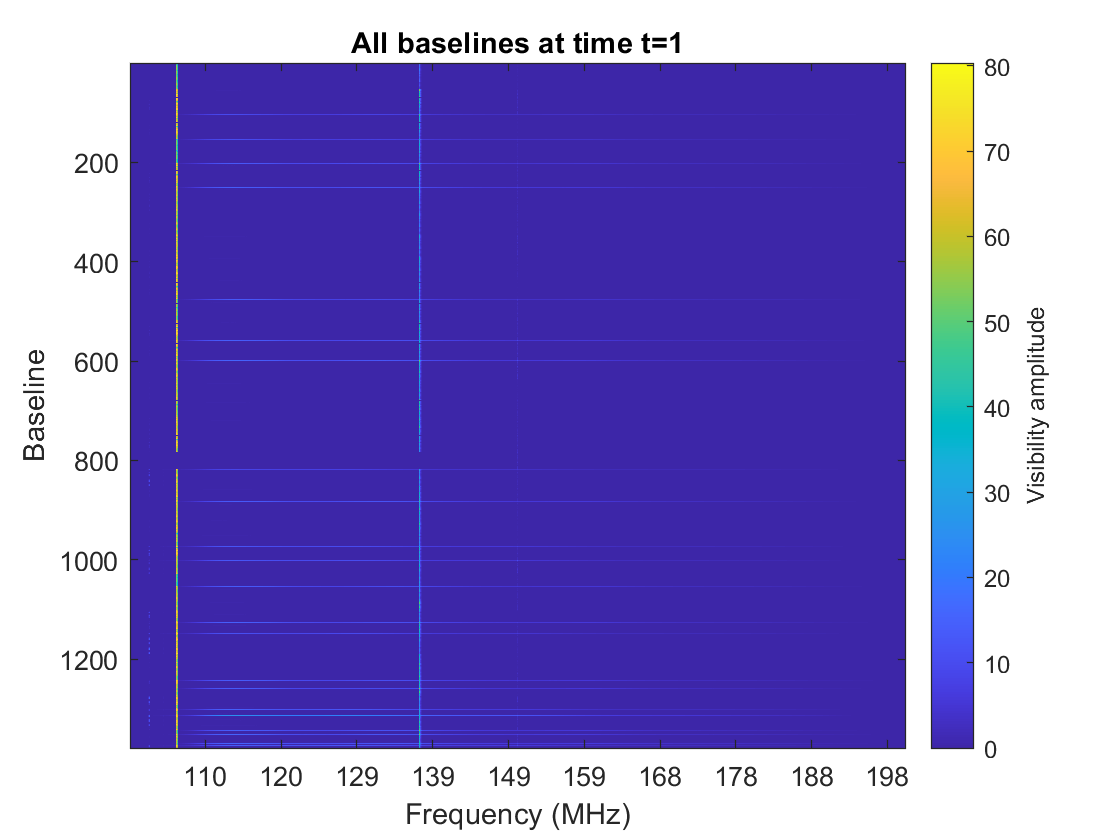

visdata_time1 = visdata_magnitude(:, :, 1, range);

%Plot the raw data for time 1
clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

We can remove these horizontal streaks of data, which correspond to baselines comprised of one antenna being correlated with itself.

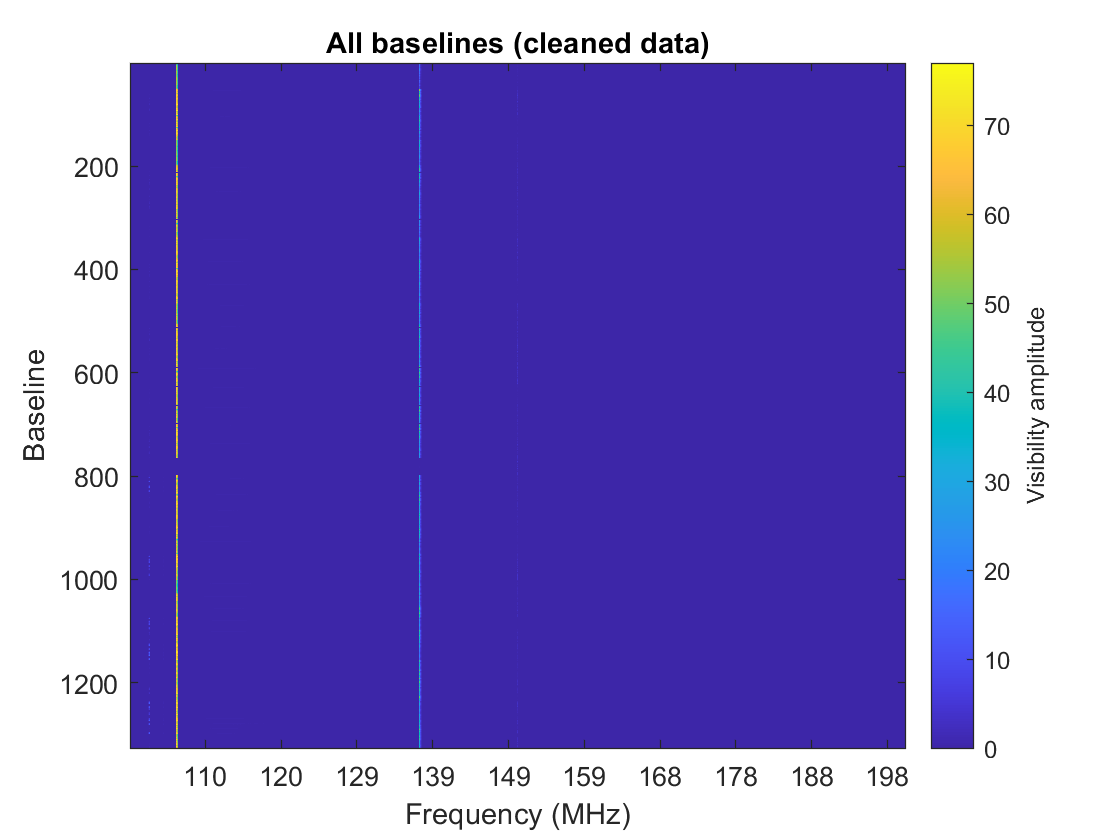

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);
clean_img = squeeze(clean_data)';
clf;
imagesc(clean_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines (cleaned data)')

baseline = [0 66];
bl = find(ismember(baselines, baseline, "rows"))

bl = 26

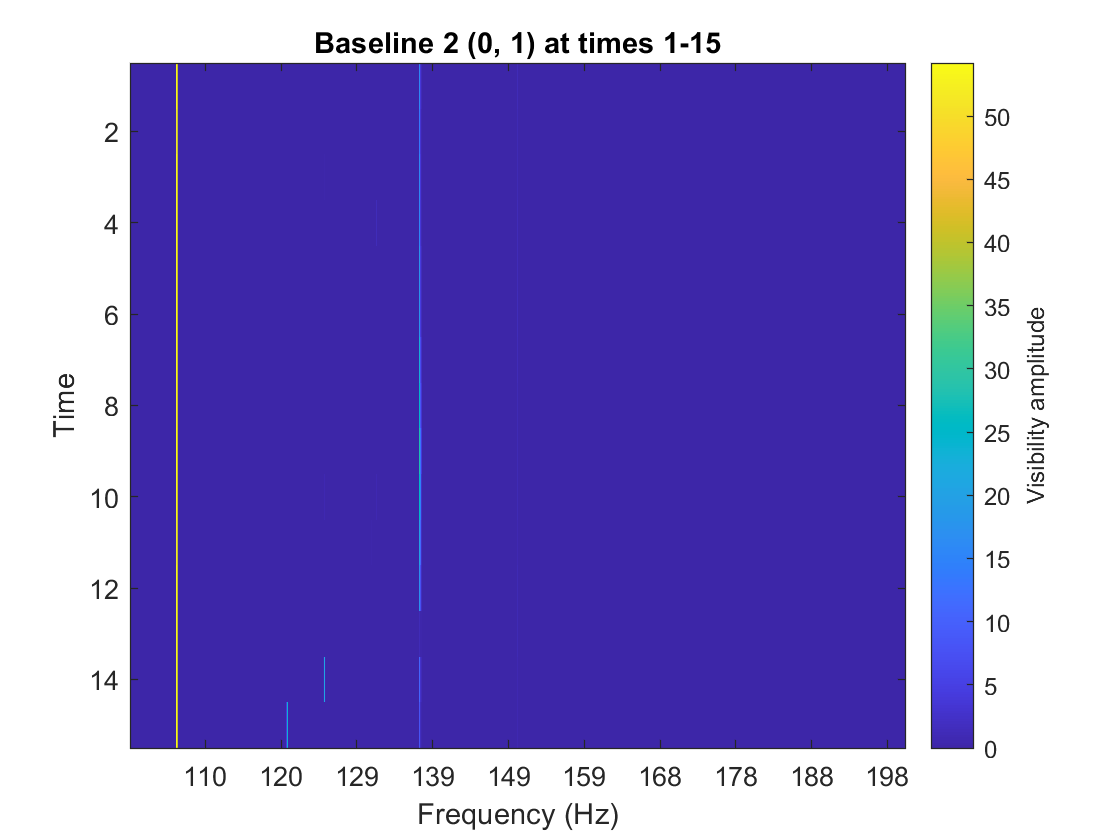

baseline_waterfall_data = visdata_magnitude(:, :, :, bl:1378:end);
waterfall_img = squeeze(baseline_waterfall_data)';

clf;
imagesc(waterfall_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (Hz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Baseline 2 (0, 1) at times 1-15');

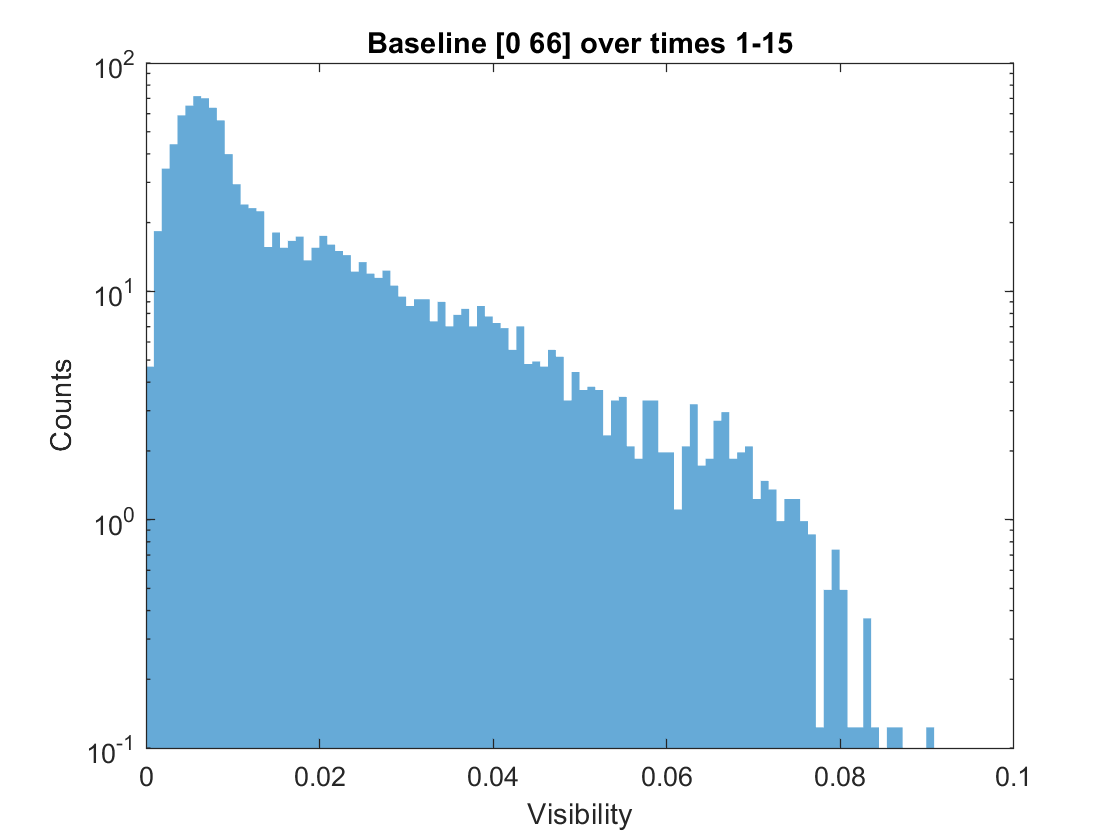

clf;
nbins = 100;
waterfall_img_limit = waterfall_img(:, 200:800);
maxval = 0.1;
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf');
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts');
xlim([0 maxval])
title(['Baseline ' mat2str(baseline) ' over times 1-15'])

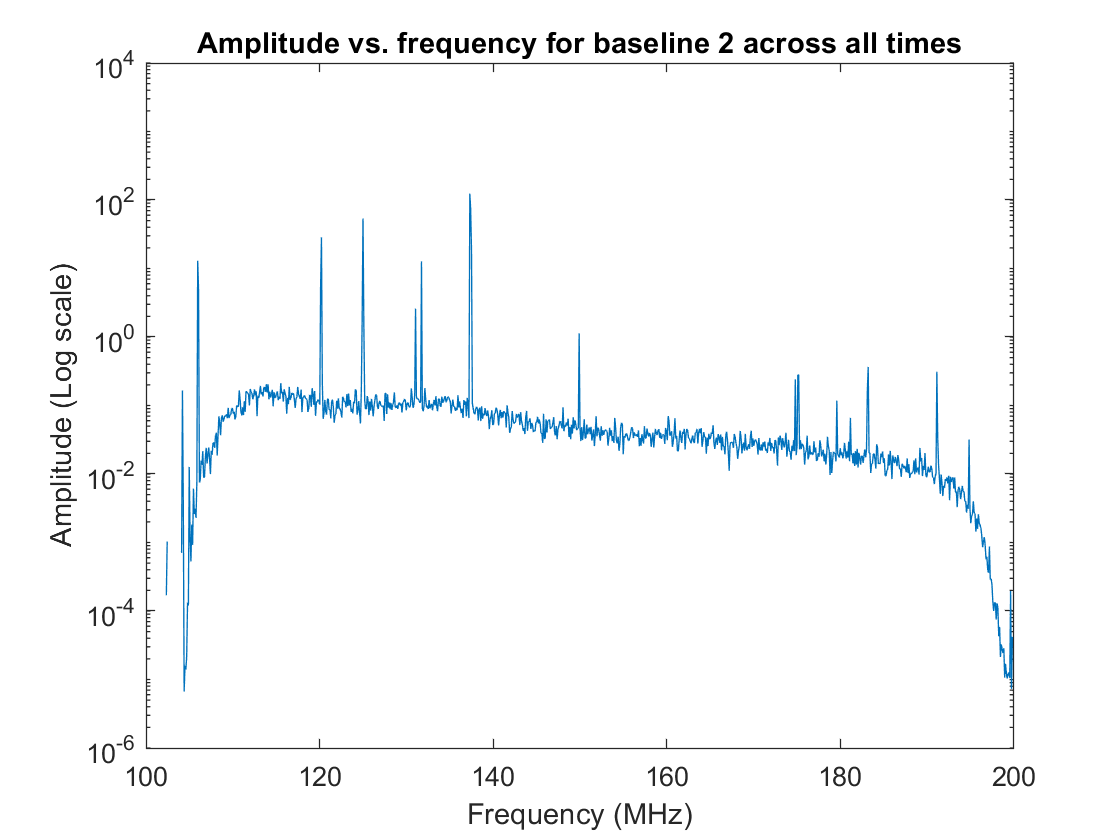


vis = squeeze(visdata_magnitude);

%Differenced times for time 1

diffs = zeros(1024, 14, 1378);
for ii = 1:1378
    diffs(:, :, ii) = diff(vis(:, ii:1378:end), 1, 2);
end

baseline = 2;
amplitude1 = sum(abs(diffs(:, :, baseline)), 2);
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for baseline 2 across all times')

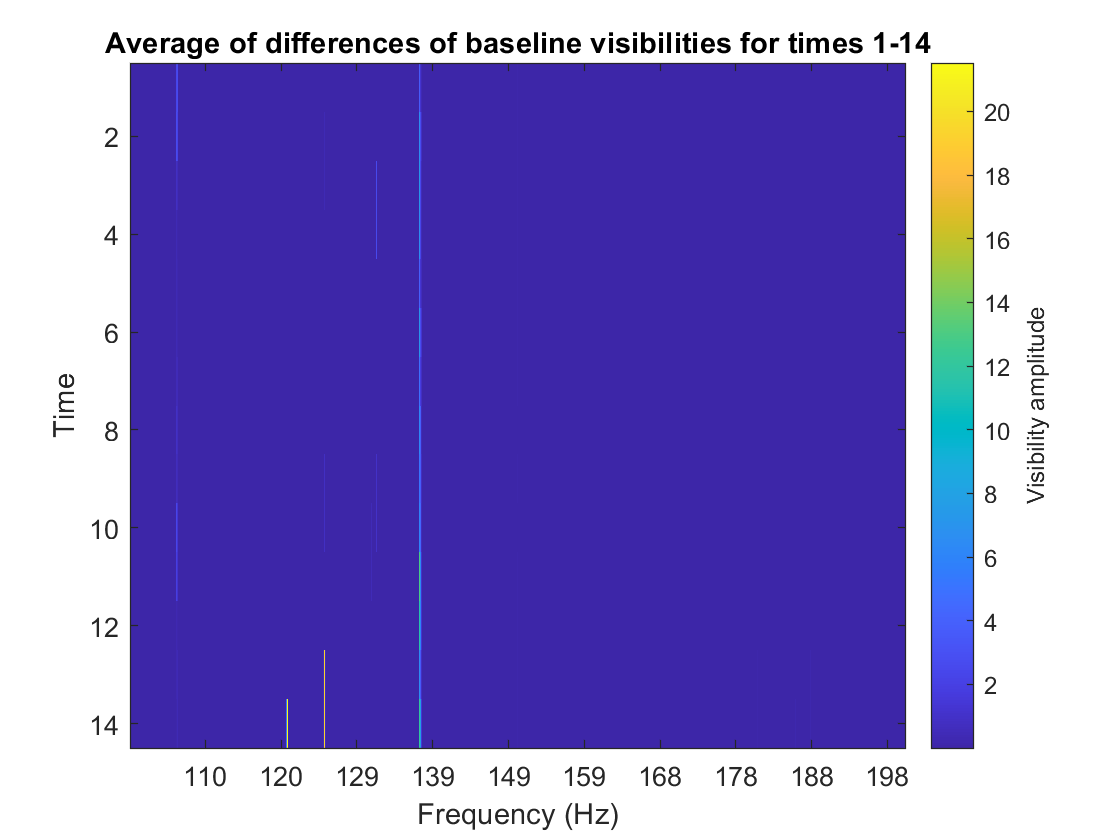

%remove vaa from data
clean_diffs = diffs(:, :, ~commonpair_indices);

averages = mean(abs(clean_diffs), 3);
clf;
imagesc(averages');
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (Hz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Average of differences of baseline visibilities for times 1-14');

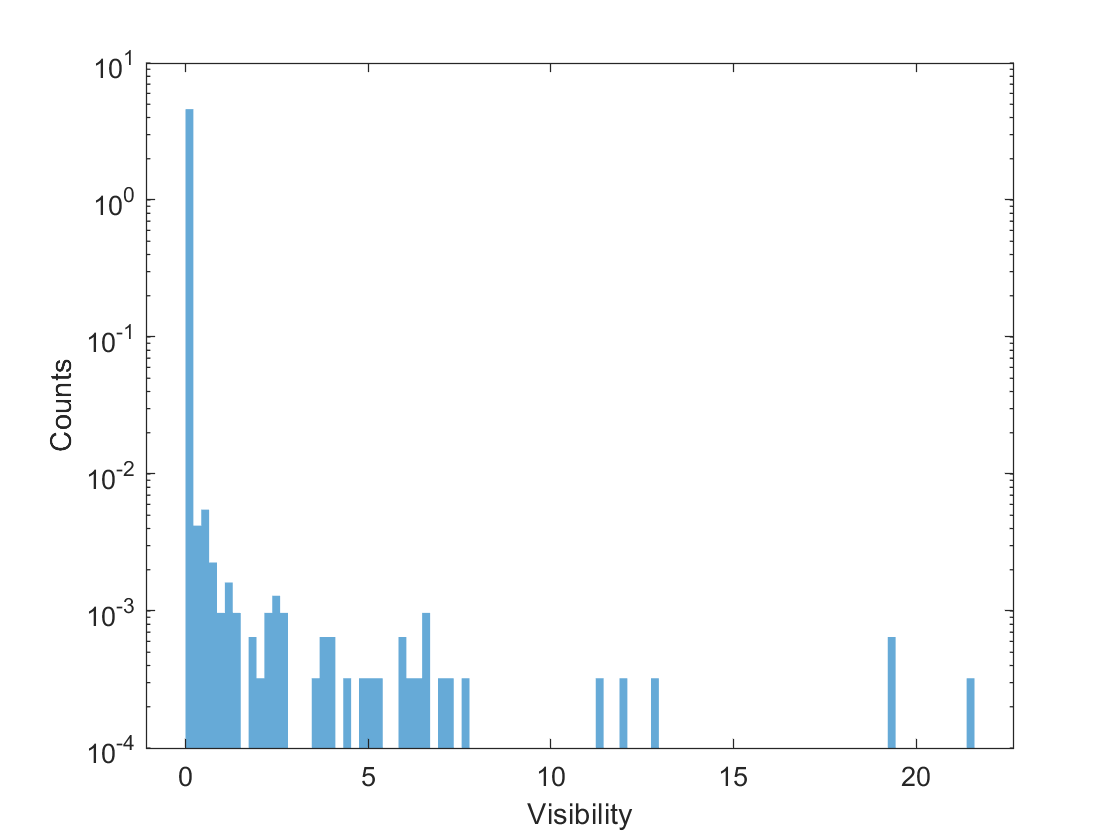

clf;
nbins = 100;
maxval = 0.1;
avg_limit = averages()
histogram(averages, nbins, 'EdgeColor', 'none', 'Normalization', 'pdf');
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts');

%xlim([0 maxval])


% times_vis = [];
% for ii = 1:1378
%     times_vis = [times_vis; vis(:, ii:1378:end)];
% end
% times_vis